load CrackData.mat
crackData

crackData = 200×4 table
    NumRegions    Area    MaxWidth     fileName  
    __________    ____    ________    ___________

        2         2461     17.889     "00001.jpg"
        2         2125     17.889     "00002.jpg"
        2         2417         16     "00003.jpg"
        1         2438     14.142     "00004.jpg"
        4         1479     18.439     "00005.jpg"
        1         2356         14     "00006.jpg"
        1         2926     18.974     "00007.jpg"
        1         2573     15.232     "00008.jpg"
        2         1861     14.142     "00009.jpg"
        2         2663     17.088     "00010.jpg"
        1         3149     23.409     "00011.jpg"
        1         2722     18.974     "00012.jpg"
        2         1221      14.56     "00013.jpg"
        1         3050      25.06     "00014.jpg"
        1         2346         14     "

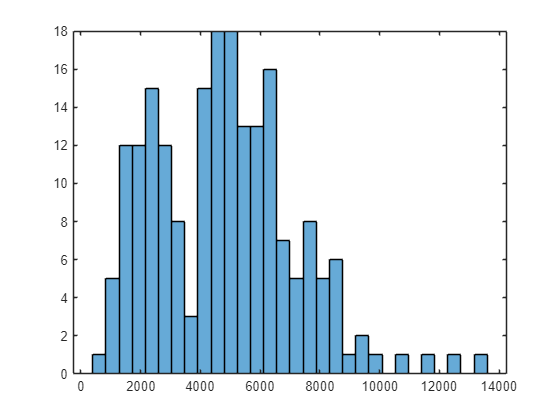

histogram(crackData.Area, 30)

The dividing line is from 4000 pixels, after wards is a crack region

cutoffArea = 4000;

% Categorizing the data, based on Area, into two categories Mild and severe
crackData.Risk = discretize(crackData.Area, [0, cutoffArea, inf], "categorical", ["Mild", "Severe"]);

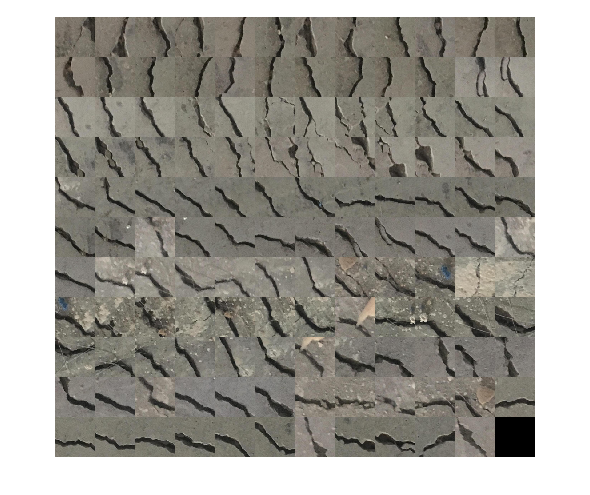

% Selecting only file which has risk equal to Severe
montage(crackData.fileName(crackData.Risk == "Severe"));

% Storing the images as Datastore, to be loaded in the image browser app
dCrackStore = imageDatastore(crackData.fileName(crackData.Risk == "Severe"))

dCrackStore =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Concrete Crack Images\00055.jpg';
                              ' ...\Data\Concrete Crack Images\00056.jpg';
                              ' ...\Data\Concrete Crack Images\00057.jpg'
                               ... and 128 more
                              }
                     Folders: {
                              ' ...\Data\Concrete Crack Images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


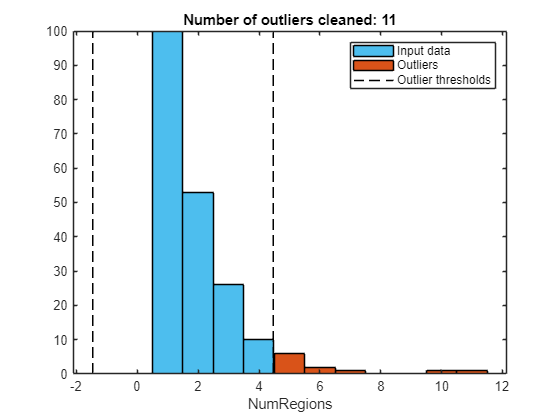

% Remove outliers
[newTable,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(crackData, ...
    "ThresholdFactor",4,"DataVariables","NumRegions");

% Display results
figure
[~,binEdges] = histcounts(crackData.NumRegions);
binEdges = unique([binEdges thresholdLow.NumRegions thresholdHigh.NumRegions]);
binEdges = binEdges(isfinite(binEdges));
histogram(crackData.NumRegions,"BinEdges",binEdges,"SeriesIndex",6, ...
    "FaceAlpha",1,"DisplayName","Input data")
hold on

% Plot outliers
histogram(crackData.NumRegions(outlierIndices),"BinEdges",binEdges, ...
    "SeriesIndex",2,"FaceAlpha",1,"DisplayName","Outliers")

% Plot outlier thresholds
plot([thresholdLow.NumRegions*[1 1] NaN thresholdHigh.NumRegions*[1 1]], ...
    [ylim missing ylim],"--","SeriesIndex","none", ...
    "DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
xlabel("NumRegions")

clear thresholdLow thresholdHigh binEdges

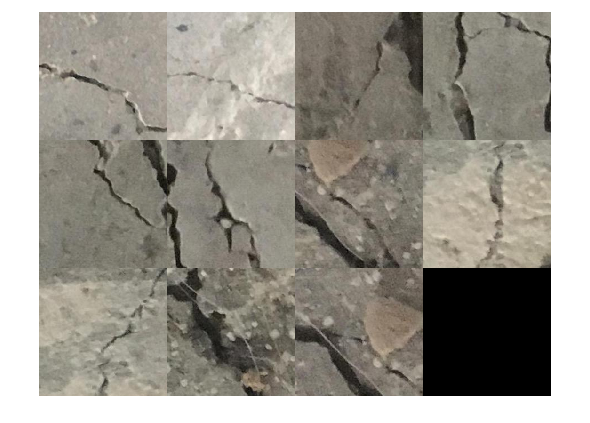

outlierImages = crackData.fileName(outlierIndices);

montage(outlierImages, "BorderSize", 1);

severeCracks = crackData(crackData.Risk == "Severe", :);

medianMaxWidthMM = median(severeCracks.MaxWidth) * 0.5;

disp(medianMaxWidthMM)

   17.4642

